**EPFL Spacecraft Team - CHESS Mission Design**

Arnaud Muller & Antoine Clout

Autumn 2020

clc
clear
close all

Read TUDAT propagation results

if (~exist('RAAN_Optimisation_Results')) %#ok<*EXIST>
    RAAN_Optimisation_Results= importdata('RAAN_Optimisation_Results.dat');
    RAANValues= importdata('RAAN_Optimisation_RAANValues.dat');
end
Epochs=RAAN_Optimisation_Results(:,1);
Time=Epochs-Epochs(1);
Timestep=Time(2);
[nb_of_epochs,tmp]=size(RAAN_Optimisation_Results);
nb_RAAN=tmp-1;
clear tmp

Compute maximum eclipse duration for each spacecraft

maxEclipse=zeros(nb_RAAN,1);
for i=1:nb_RAAN
    compteur = 0;
    Eclipses = zeros(nb_of_epochs,1);
    for k=1:nb_of_epochs
        if RAAN_Optimisation_Results(k,i+1) > 0
            Eclipses(k) = compteur;
            compteur = 0;
        else
            compteur = compteur +1;
        end
    end
    if sum(Eclipses(end-1,1)==0)
        Eclipses(k) =0;
    else
        Eclipses(k) = compteur;
    end
    clear compteur
    Eclipses=Timestep*Eclipses(Eclipses > 0);
    if isempty(max(Eclipses))
        maxEclipse(i)=0;
    else
        maxEclipse(i)=max(Eclipses);
    end
end

Find LTAN of RAAN value corresponding to a maximal eclipse duration

addpath('./mltan');
jdate=Epochs(1)+juliandate(2000,01,01,12,0,0);
LTANValues=raan2mltan(jdate, deg2rad(RAANValues));


RAANValues_maxEclipse=RAANValues(maxEclipse==max(maxEclipse));
raan_maxeclipse=mean(RAANValues_maxEclipse(RAANValues_maxEclipse<mean(RAANValues_maxEclipse)));

LTAN_maxeclipse=raan2mltan(jdate, deg2rad(raan_maxeclipse));

[H,M,S] = hms(hours(LTAN_maxeclipse));
disp('Local Time at Ascending Node for a maximal eclipse duration :')

Local Time at Ascending Node for a maximal eclipse duration :


disp(append(num2str(H),' hours ',num2str(M),' minutes ',num2str(S),' seconds.'))

14 hours 0 minutes 50.4881 seconds.


Plot Results

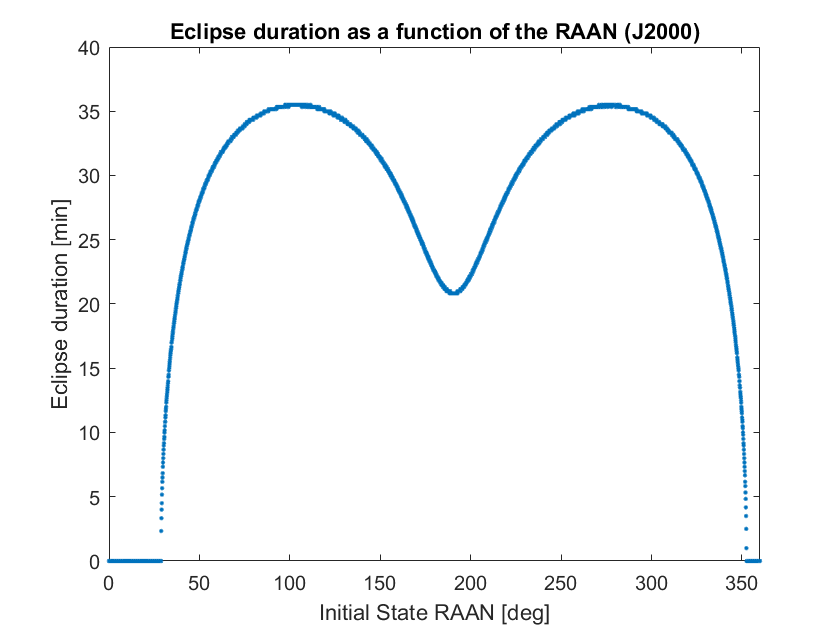

figure
plot(RAANValues,maxEclipse/60,'.')
xlim([0 360])
xlabel('Initial State RAAN [deg]')
ylabel('Eclipse duration [min]')
title('Eclipse duration as a function of the RAAN (J2000)')

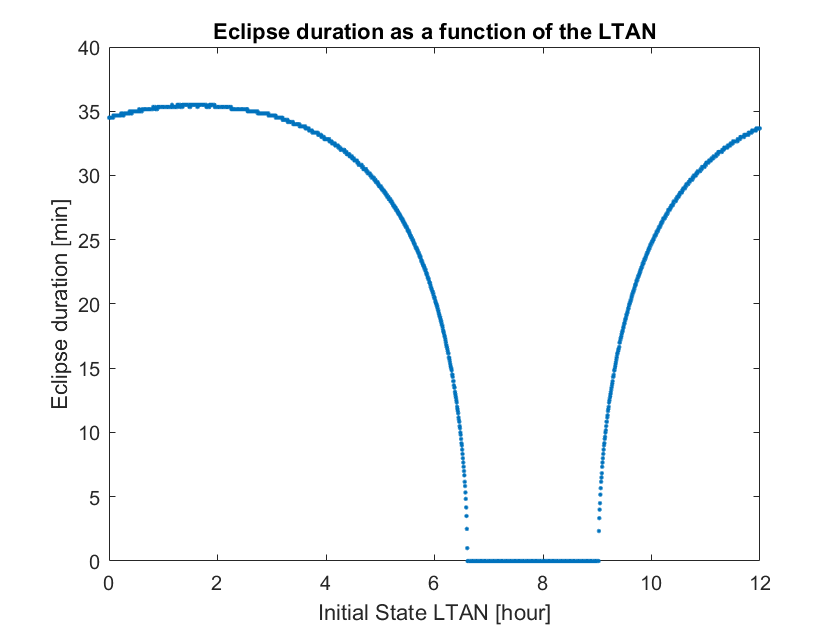


figure
plot(mod(LTANValues,24),maxEclipse/60,'.')
xlim([0 12])
xticks(0:2:24)
xlabel('Initial State LTAN [hour]')
ylabel('Eclipse duration [min]')
title('Eclipse duration as a function of the LTAN')